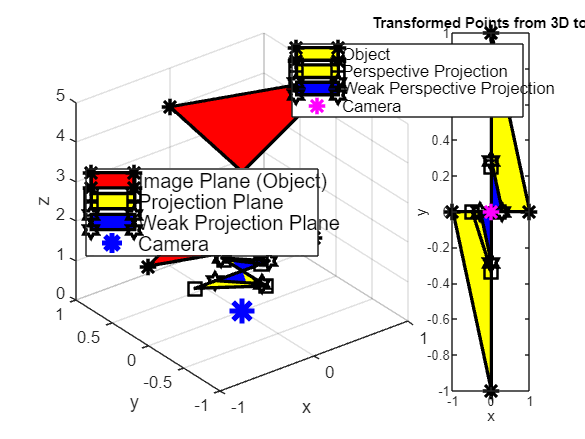

clear; clc; close all;

% Define coordinate points
Points = [-1, 0, 2; 1, 0, 5; 0, 1, 4; 0, -1, 3];

% Define focal length
focal_length = 1;

% Project coordinates using perspective and weak perspective projections
Pers_Projection = perspective(Points, focal_length);
WPers_Projection = weak_perspective(Points, focal_length);

% Plot the original and projected coordinates
plotting(Points, Pers_Projection, WPers_Projection);

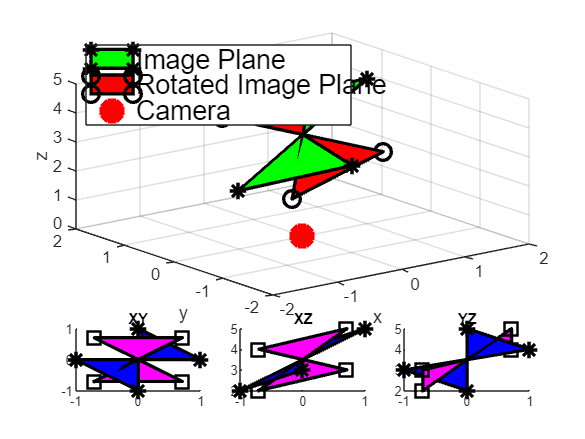


% Calculate SSD between projected coordinates
ssd(Pers_Projection, WPers_Projection);

% Define rotation angle in degrees
theta = 45;

% Rotate the object
Rotate_Projection = rotation(theta, Points);

% Define camera position
Camera_Position = [0, 0, 0];

% Plot the rotated object and projected points
plot_object(Points, Rotate_Projection, Camera_Position);

% Project rotated coordinates using perspective and weak perspective projections
RPers_Projection = perspective(Rotate_Projection, focal_length);
RWPers_Projection = weak_perspective(Rotate_Projection, focal_length);

% Plot the rotated and projected coordinates
plot_object(Points, Rotate_Projection, Camera_Position);

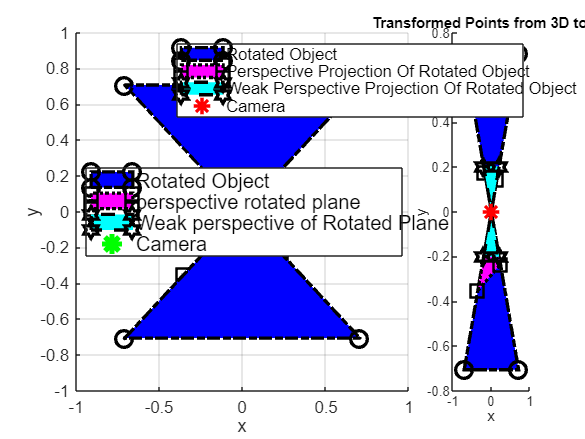


% Plot the rotated object and compare original and rotated projections
rotated_plot(Rotate_Projection, Pers_Projection, WPers_Projection, RPers_Projection, RWPers_Projection);


% Calculate SSD between rotated projected coordinates
D = ssd(RPers_Projection, RWPers_Projection);



function Pers_Projection = perspective(Points, focal_length)
    % P is a matrix of 3D coordinates
    % f is the focal length
    
    % Extract the z-coordinate of each point
    Z = Points(:, 3);
    
    % Compute the perspective projection for each point
    Pers_Projection = bsxfun(@times, Points(:, 1:2), focal_length ./ Z);
end


function plot_object(Points,Rotate_Projection,Camera_Position)

figure(2);

subplot(4,3,[1 9])
fill3(Points(:,1),Points(:,2),Points(:,3),'-g*','MarkerSize',10,'LineWidth',2);
hold on
fill3(Rotate_Projection(:,1),Rotate_Projection(:,2),Rotate_Projection(:,3),'-ro','MarkerSize',10,'LineWidth',2);
hold on
hold on
plot3(Camera_Position(1,1), Camera_Position(1,2),Camera_Position(1,3),'r*', 'MarkerSize',15,'LineWidth',5)
legend('Image Plane','Rotated Image Plane','Camera','Location','northwest','FontSize',16 )
xlabel('x')
ylabel('y')
zlabel('z')
grid on
axis([-2,2,-2,2,0,5])
subplot(4,3,10)
fill3(Points(:,1),Points(:,2),Points(:,3),'-b*','MarkerSize',10,'LineWidth',2);
hold on
fill3(Rotate_Projection(:,1),Rotate_Projection(:,2),Rotate_Projection(:,3),'-ms','MarkerSize',10,'LineWidth',2);
view(0,90)
% xlabel('x')
% ylabel('y')
title('XY')
subplot(4,3,11)
fill3(Points(:,1),Points(:,2),Points(:,3),'-b*','MarkerSize',10,'LineWidth',2);
hold on
fill3(Rotate_Projection(:,1),Rotate_Projection(:,2),Rotate_Projection(:,3),'-ms','MarkerSize',10,'LineWidth',2);
view(0,0) % XZ
% xlabel('x')
% ylabel('z')
title('XZ')
subplot(4,3,12)
fill3(Points(:,1),Points(:,2),Points(:,3),'-b*','MarkerSize',10,'LineWidth',2);
hold on
fill3(Rotate_Projection(:,1),Rotate_Projection(:,2),Rotate_Projection(:,3),'-ms','MarkerSize',10,'LineWidth',2);
view(90,0) % YZ
% xlabel('y')
% ylabel('z')
title('YZ')
end

function plotting(Points, Pers_Projection, WPers_Projection)
    figure; 
    subplot(1,4,[1 3]);
    fill3(Points(:,1),Points(:,2),Points(:,3),'-r*', Pers_Projection(:,1),Pers_Projection(:,2),ones(size(Pers_Projection,1),1),'-ys', ...
    WPers_Projection(:,1),WPers_Projection(:,2),ones(size(WPers_Projection,1),1),'-bh','MarkerSize',10,'LineWidth',2);
    hold on;
    plot3(0,0,0, 'b*', 'MarkerSize',15,'LineWidth',3);
    legend('Image Plane (Object)','Projection Plane','Weak Projection Plane','Camera',...
           'FontSize',12,'Location','west' );
    axis([-1,1,-1,1,0,5]);
    xlabel('x'); ylabel('y'); zlabel('z');
    grid on;
    subplot(1,4,4);
    fill(Points(:,1),Points(:,2),'-y*', Pers_Projection(:,1),Pers_Projection(:,2),'-ys', WPers_Projection(:,1),WPers_Projection(:,2),'-bh',...
    'MarkerSize', 10,'LineWidth',2);
    hold on;
    plot(0,0,'m*', 'MarkerSize', 10,'LineWidth',2);
    title('Transformed Points from 3D to 2D');
    legend('Object','Perspective Projection','Weak Perspective Projection','Camera',...
           'FontSize',10);
    xlabel('x'); ylabel('y');
end

function rotated_plot(Rotate_Projection,Pers_Projection,WPers_Projection,RPers_Projection,RWPers_Projection)
    Pers_Projection(:,1); 
    Pers_Projection(:,2); 
    
    WPers_Projection(:,1); 
    WPers_Projection(:,2);
    
    xcRR = RPers_Projection(:,1); 
    ycRR = RPers_Projection(:,2); 
    
    xwRR = RWPers_Projection(:,1); 
    ywRR = RWPers_Projection(:,2);
    
    figure(3); 
    
    subplot(1,4,[1 3]); hold on;
    fill3(Rotate_Projection(:,1),Rotate_Projection(:,2),Rotate_Projection(:,3),'bo-','MarkerSize',10,'LineWidth',2,'LineStyle','-.', 'edgecolor','k');
    fill3(RPers_Projection(:,1),RPers_Projection(:,2),ones(size(RPers_Projection,1),1),'ms-','MarkerSize',10,'LineWidth',2,'LineStyle',':', 'edgecolor','k');
    fill3(RWPers_Projection(:,1),RWPers_Projection(:,2),ones(size(RWPers_Projection,1),1),'ch-','MarkerSize',10,'LineWidth',2,'LineStyle','--', 'edgecolor','k');
    plot3(0,0,0,'g*', 'MarkerSize',15,'LineWidth',3);
    axis([-1,1,-1,1,0,5]); xlabel('x'); ylabel('y'); zlabel('z'); grid on;
    legend('Rotated Object','perspective rotated plane','Weak perspective of Rotated Plane','Camera','FontSize',12,'Location','west');
    
    subplot(1,4,4); hold on;
    fill(Rotate_Projection(:,1),Rotate_Projection(:,2),'bo-','MarkerSize',10,'LineWidth',2,'LineStyle','-.');
    fill(xcRR,ycRR,'ms-','MarkerSize',10,'LineWidth',2,'LineStyle',':');
    fill(xwRR,ywRR,'ch-','MarkerSize',10,'LineWidth',2,'LineStyle','--');
    plot(0,0,'r*', 'MarkerSize',10,'LineWidth',2);
    title('Transformed Points from 3D to 2D');
    xlabel('x'); ylabel('y');
    legend('Rotated Object','Perspective Projection Of Rotated Object','Weak Perspective Projection Of Rotated Object','Camera','FontSize',10);
end


function Rotate_Projection = rotation(theta, Points)
% P is the coordinates and theta is the angle of rotation in degrees
Rz = [cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1]; % rotation matrix about z-axis
Rotate_Projection = (Rz * Points')'; % apply rotation to points
end


function D = ssd(Pers_Projection, WPers_Projection)
D = sum(sum(abs(Pers_Projection - WPers_Projection).^2));
end

function WPers_Projection = weak_perspective(Points, focal_length)
    % Points is a matrix of 3D coordinates
    % f is the focal length
    
    % Compute the mean z-coordinate of all points
    Z0 = mean(Points(:, 3));

    % Compute the weak perspective projection for each point
    WPers_Projection = bsxfun(@times, Points(:, 1:2), focal_length ./ Z0);
end
